## **Practice Problems 7 - Linear Regression**

1 - 4) Use least squares regression to fit a straight line to the following data (implement the formula from the lectures in Matlab).

% Plot the table in graph
x = [0, 2, 4, 6, 9, 11, 12, 15, 17, 19];
y = [5, 6, 7, 6, 9, 8, 8, 10, 12, 12];


% Plot the linear equation on graph
p = polyfit(x, y, 1) % gives the linear equation m and c for y = mx + c

p =     0.3591    4.8881


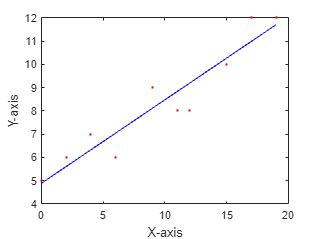

linY = polyval(p, x);

plot(x, y, 'r.', x, linY, 'b');
xlabel("X-axis")
ylabel("Y-axis")

2) Calculate the correlation coefficient for the best fit line from question 1.

disp(corrcoef(linY, y))

    1.0000    0.9449
    0.9449    1.0000



4)* The following data were gathered to determine the relationship between pressure and temperature of a fixed volume of 1 kg of nitrogen (molar mass of 14.006747 g/mol). The volume is 10m3. Use the ideal gas law equation to determine the universal gas constant, R.

T = [-40, 0, 40, 80, 120, 160]; % Temperature in C
T_Kelvin = T + 273.15;% Temperature in K
P = [6900, 8100, 9350, 10500, 11700, 12800]; % Pressure
PV = P * 10; % Multiplying P and V to get the new Y
nT = T_Kelvin * 1000/28.02; % Multiplying n (mass/molar mass)
% So the equation will be Y = RX
m = polyfit(nT, PV, 1) % Find Linear Equation

m =     8.2959  280.4702



% plot(T, P, 'r.', T, newP, 'b');

5) Linearise the following model and use it to estimate the parameters α4 and β4 for the following data. Plot the data with the line of best fit and calculate the correlation coefficient.

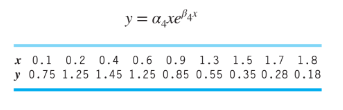

x5 = [0.1, 0.2, 0.4, 0.6, 0.9, 1.3, 1.5, 1.7, 1.8];
y5 = [0.75, 1.25, 1.45, 1.25, 0.85, 0.55, 0.35, 0.28, 0.18];

% linearize and got ln(y) = ln(a4) + ln(x) + 4^x
lnY = log(y5);
lnX = log(x5);
xLnx = lnX + x5

xLnx =    -2.2026   -1.4094   -0.5163    0.0892    0.7946    1.5624    1.9055    2.2306    2.3878



pp = polyfit(xLnx, lnY, 1)

pp =    -0.3451   -0.2885


pp1 = exp(pp(2))

ans = 0.7494

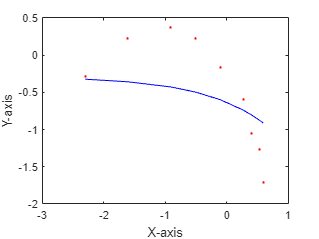

finalX = ()

plot(lnX, lnY, 'r.', lnX, ppY, 'b');
xlabel("X-axis")
ylabel("Y-axis")

6) Try fitting a power equation to the following data on metabolisms of animals then using it to predict the metabolism rate of a 200kg tiger.

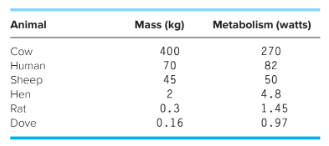

% Power Equation: log y = log a + b log x
% x = mass, y = Metabolim

mass = [400, 70, 45, 2, 0.3, 0.16];
metabolism = [270, 82, 50, 4.8, 1.45, 0.97];
logMass = log(mass);
logMet = log(metabolism);

p6 = polyfit(logMass, logMet, 1);
a = p6(1);
b = exp(p6(2));
fitMet = b * mass .^ a;
disp(b * 200 ^ a);

  159.2047



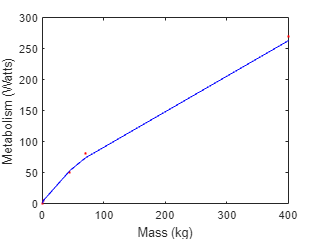


plot(mass, metabolism, 'r.', mass, fitMet, 'b');
xlabel("Mass (kg)")
ylabel("Metabolism (Watts)")

7) The following data represents bacteria growth. Two models have been proposed for this growth:

Where k is the growth rate and c is the concentration. Fit the data below to both of these models by transforming them into linear relationships and finding the parameters *km* and *cs*. Which model fits the data better? Predict the growth of bacteria when c = 2 mg/L.

c = [0.5, 0.8, 1.5, 2.5, 4]

c =     0.5000    0.8000    1.5000    2.5000    4.0000


k = [1.1, 2.5, 5.3, 7.6, 8.9]

k =     1.1000    2.5000    5.3000    7.6000    8.9000


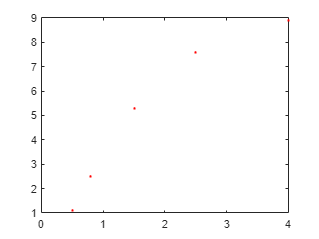


plot(c, k, 'r.')

8) A transportation engineering study was conducted to determine the proper design of bike lanes. Data were gathered on bike lane widths and average distance between bikes and passing cars. The data from 9 streets are:

a) Plot the data

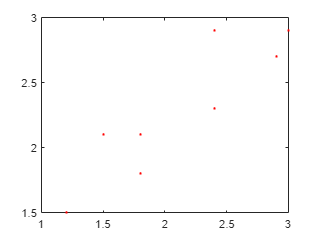

d = [2.4, 1.5, 2.4, 1.8, 1.8, 2.9, 1.2, 3, 1.2];
l = [2.9, 2.1, 2.3, 2.1, 1.8, 2.7, 1.5, 2.9, 1.5];

plot(d, l, 'r.')

b) Fit a straight line to the data with linear regression. Add this line to the plot.

p8 = polyfit(d, l, 1)

p8 =     0.7335    0.7167


newp8 = polyval(p8, d)

newp8 =     2.4771    1.8170    2.4771    2.0370    2.0370    2.8438    1.5969    2.9172    1.5969


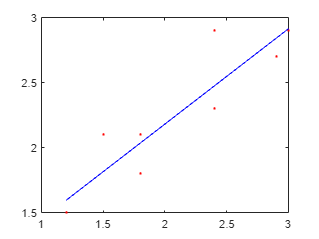

plot(d, l, 'r.', d, newp8, 'b')

c) If the minimum safe average distance between bikes and passing cars is considered to be 1.8m, determine the corresponding minimum lane width.

disp(p8(1) * 1.8 + p8(2))

    2.0370



9) The table below shows the 2015 world record times and holders for outdoor running. **Fit a power model **for each gender and use it to predict the record time for a half marathon (21,097.5m). Note: the actual records for the half marathon are 3503s (Tadese) and 3909s (Kiplagat) for men and women, respectively.

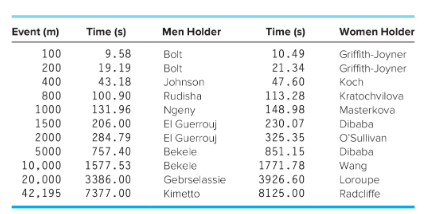

event = [100, 200, 400, 800, 1000, 1500, 2000, 5000, 10000, 20000, 42195];
menTime = [9.58, 19.19, 43.18, 100.90, 131.96, 206.00, 284.79, 757.40, 1577.53, 3386.00, 7377.00];
womenTime = [10.49, 21.34, 47.60, 113.28, 148.98, 230.07, 325.35, 851.15, 1771.78, 3926.60, 8125.00];

% Men
pMen = polyfit(event, menTime, 1)

pMen =     0.1749  -59.7745


pVal = polyval(pMen, event)

pVal = 1.0e+03 *

   -0.0423   -0.0248    0.0102    0.0801    0.1151    0.2026    0.2900    0.8147    1.6893    3.4383    7.3203


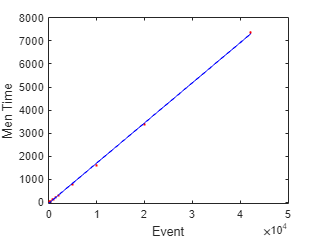

plot(event, menTime, 'r.', event, pVal, 'b')
xlabel("Event")
ylabel("Men Time")

disp(pMen(1) * 21097.5 + pMen(2))

   3.6302e+03




pWomen = polyfit(event, womenTime, 1)

pWomen =     0.1940  -51.9883


pWVal = polyval(pWomen, event)

pWVal = 1.0e+03 *

   -0.0326   -0.0132    0.0256    0.1032    0.1421    0.2391    0.3361    0.9182    1.8885    3.8289    8.1357


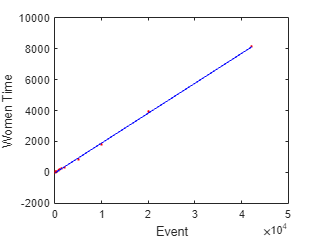

plot(event, womenTime, 'r.', event, pWVal, 'b')
xlabel("Event")
ylabel("Women Time")

disp(pWomen(1) * 21097.5 + pWomen(2))

   4.0419e+03



Functions